# Example 118 Bus System - EMT

Copyright © 2025, The MathWorks, Inc.

## Introduction

There are two parts to this workflow. 

First, we will use [MATPOWER](https://github.com/MATPOWER/matpower) (a MATLAB Community Toolbox) to perform a load flow calculation of an example 118 bus system. A load flow is a fundamental calculation performed by power systems engineers, to calculate an operating point of an electric grid and connected assets. Load flow calculations use optimization to determine the power levels on generators and loads, as well as the voltage levels on the network buses (nodes).

Second, we will use the information from MATPOWER to build the network model of the example 118 bus system using Simscape™ Electrical™ for use in EMT simulation. The model is then connected to dynamic assets for subsequent dynamic simulation. 

Use MathWorks Release R2025b,

MATLAB®

Simulink®

Simscape™

Simscape™ Electrical™

MATPOWER 8.0 (MathWorks Community Toolbox)

Simscape Electrical Support Library for Power System Engineers

## Load Flow

The network data for the example 118 bus system is contained within the file case118.m in MATPOWER. The function loadcase in MATPOWER reads the case data into a data structure.

bdclose all
clear

data = loadcase('case118');

This system has 19 generators, 35 synchronous condensers, 118 buses (nodes), 175 branches (cables), and 101 loads.

Now we can calculate a basic load flow using the function runpf in MATPOWER. The results are stored to a new data structure.

data1 = runpf(data)


MATPOWER Version 8.0, 17-May-2024
Power Flow -- AC-polar-power formulation

Newton's method converged in 3 iterations.
PF successful

Converged in 1.30 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses            118     Total Gen Capacity    9966.2       -7345.0 to 11777.0
Generators        54     On-line Capacity      9966.2       -7345.0 to 11777.0
Committed Gens    54     Generation (actual)   4374.9             795.7
Loads             99     Load                  4242.0            1438.0
  Fixed           99       Fixed               4242.0            1438.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0      

data1 = struct with fields:
       version: '2'
       baseMVA: 100
           bus: [118×13 double]
           gen: [54×21 double]
        branch: [186×17 double]
       gencost: [54×7 double]
      bus_name: {118×1 cell}
         order: [1×1 struct]
          task: [1×1 mp.task_pf_legacy]
            et: 1.2969
       success: 1
    iterations: 3
            om: [1×1 mp.math_model_pf_acps]


Use a graph to display the network as 2 segments. n1 is a vector of bus numbers in segment 1. n2 is a vector of bus numbers in segment 2. linesConn contains the from and to line connections that separate segment 1 from segment 2. In the network display, segment 1 is blue, segment 2 is red, and the green lines are the connector lines.

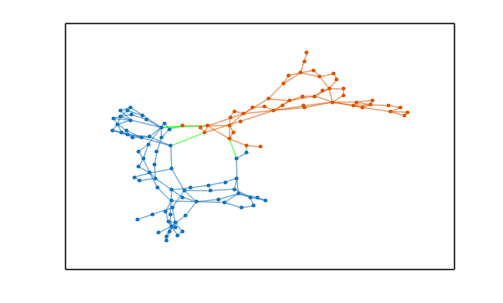

[X,Y,~,~,~,~,n1,n2,linesConn] = displayGraph_2segs(data,0.7);

## Additional Parameters for Model Build

Ts = 5e-5;

% from and to voltage levels on the branches
[~,idxf] = ismember(data1.branch(:,1),data1.bus(:,1));
[~,idxt] = ismember(data1.branch(:,2),data1.bus(:,1));
data1.fV = data1.bus(idxf,10);
data1.tV = data1.bus(idxt,10);
data1.X = X*800;
data1.Y = Y*800+1600;

freq = 60; % nominal (rated) frequency

genBus = unique(data1.gen(:,1));

idxLoad = data1.bus(:,3)~=0 | data1.bus(:,4)~=0 | data1.bus(:,6)~=0;
data1.busLoad = unique(data1.bus(idxLoad,1));
data1.busGenPV = data1.bus(data1.bus(:,2) == 2 | data1.bus(:,2) == 3,1);

ww = arrayfun(@num2str, unique(data1.bus(:,10)), 'UniformOutput', false);
voltageLevels = cellfun(@(x) strrep(x,'.','p'),ww,'UniformOutput',false);

## Build the EMT Model

nv  = [{'n1'},{'n2'}];

for x = 1:2

clear data

nn  = eval(nv{x});

data.baseMVA = data1.baseMVA;

buses1 = data1.bus(nn,1);

idxLines = ismember(data1.branch(:,1),buses1) & ismember(data1.branch(:,2),buses1);
data.branch = data1.branch(idxLines,:);

idxBuses = ismember(data1.bus(:,1),buses1);
data.bus = data1.bus(idxBuses,:);

data.fV = data1.fV(idxLines);
data.tV = data1.tV(idxLines);
data.X = data1.X(idxBuses);
data.Y = data1.Y(idxBuses);

idxGens = ismember(data1.gen(:,1),buses1);
data.gen = data1.gen(idxGens,:);

idxLoad = data.bus(:,3)~=0 | data.bus(:,4)~=0 | data.bus(:,6)~=0;
data.busLoad = unique(data.bus(idxLoad,1));
data.busGenPV = data.bus(data.bus(:,2) == 2 | data.bus(:,2) == 3,1);

Open the blank canvas

mdl = 'blank_canvas_118';
open_system(mdl)

Add the buses 

bus_placement(mdl,data)
disp('buses done')

buses done


buses done


Add the lines

branch_placement_bergeron(mdl,data,freq,Ts)
disp('lines done')

lines done


lines done


Define inputs

clear tagI
tagI = define_inputs(mdl,voltageLevels);
eval([nv{x},'_tagI = tagI;'])

Define outputs

define_outputs(mdl,voltageLevels)

Add the Simscape Solver Configuration block

% find the first bus
hb = find_system(mdl,'FindAll','on','Name',['node_',num2str(data.bus(1,1))]);

% copy solver configuration over to model
hsc = add_block('nesl_utility/Solver Configuration',[mdl,'/Solver Configuration']);

% put solver configuration near the bus
psc = get(hsc,'Position');
pos = psc - [psc(1) psc(2) psc(1) psc(2)];
pb = get(hb,'Position');
set(hsc,'Position',pos + [pb(1)-150 pb(2)-50 pb(1)-150 pb(2)-50])

% get port handles
b1 = get(hb,'Porthandles');
b2 = get(hsc,'Porthandles');

% connect the solver configuration to the bus
add_line(mdl,b1.LConn(1),b2.RConn(1))

% configure the solver parameters for large-scale simulation
set(hsc,'EquationFormulation','NE_TIME_EF')
set(hsc,'IndexReductionMethod','None')
set(hsc,'ConsistencyTolSource','LOCAL')
set(hsc,'ConsistencyAbsTol','1e4')
set(hsc,'ConsistencyRelTol','1e4')
set(hsc,'ConsistencyTolFactor','1')
set(hsc,'UseLocalSolver','on')
set(hsc,'DoFixedCost','on')
set(hsc,'MaxNonlinIter','1')
set(hsc,'ResolveIndetEquations','off')
set(hsc,'LocalSolverChoice','NE_BACKWARD_EULER_ADVANCER')
set(hsc,'LocalSolverSampleTime','Ts')
set(hsc,'LinearAlgebra','Sparse')
set(hsc,'AutomaticFiltering','off')

Define Bus Signal Objects

warning('off','Simulink:utility:slUtilityCompBusCannotUseSignalNameForBusName')

clear slB*

mdl1 = 'busCreators01';

open_system(mdl1)

% delete the existing blocks
try
    delete_block([mdl1,'/measurements']);
catch
end

% Copy measurements subsystem from mdl to mdl1

hv1 = add_block([mdl,'/measurements'],[mdl1,'/measurements']);

hbc = find_system(mdl1,'FindAll','on','BlockType','BusCreator');
set(hbc,'OutDataTypeStr','Inherit: auto')

hop = find_system(mdl1,'FindAll','on','BlockType','Outport');
set(hop,'OutDataTypeStr','Inherit: auto')

for xx = 1:numel(voltageLevels)

    busInfo1 = Simulink.Bus.createObject(mdl1,[mdl1,'/measurements/bus_',voltageLevels{xx},'kV_outputs/bus_',voltageLevels{xx},'kV_output_bus']); %#ok<*NASGU>
    eval([nv{x},'_slBus',num2str(xx),' = eval(busInfo1.busName);']); %#ok<*EVLSEQVAR>
    clear busInfo1

end

busInfo1 = Simulink.Bus.createObject(mdl1,[mdl1,'/measurements/line_current_outputs/line_current_output_bus']);
eval([nv{x},'_slBus',num2str(xx+1),' = eval(busInfo1.busName);']); %#ok<*EVLSEQVAR>
clear busInfo1

for xx = 1:numel(voltageLevels)

    h1 = find_system(mdl1,'FindAll','on','BlockType','Outport','Name',['V_',voltageLevels{xx},'kV']);
    set(h1,'OutDataTypeStr',['Bus: ',nv{x},'_slBus',num2str(xx)])
    clear h1

end

h1 = find_system(mdl1,'FindAll','on','BlockType','Outport','Name','I_line');
set(h1,'OutDataTypeStr',['Bus: ',nv{x},'_slBus',num2str(xx+1)])
clear h1

busInfo1 = Simulink.Bus.createObject(mdl1,[mdl1,'/measurements/meas_bus']);
eval([nv{x},'_slBus',num2str(xx+2),' = eval(busInfo1.busName);']); 
clear busInfo1


for yy = 1:numel(voltageLevels)+1

    for x1 = 1:numel(eval([nv{x},'_slBus',num2str(yy),'.Elements']))
        eval([nv{x},'_slBus',num2str(yy),'.Elements(x1).Dimensions = 3;'])
    end

end

save_system(mdl1)
close_system(mdl1)

for xx = 1:numel(voltageLevels)

    h1 = find_system(mdl,'FindAll','on','BlockType','Outport','Name',['V_',voltageLevels{xx},'kV']);
    set(h1,'OutDataTypeStr',['Bus: ',nv{x},'_slBus',num2str(xx)])

end

h1 = find_system(mdl,'FindAll','on','BlockType','Outport','Name','I_line');
set(h1,'OutDataTypeStr',['Bus: ',nv{x},'_slBus',num2str(xx+1)])
clear h1

h1 = find_system(mdl,'FindAll','on','BlockType','Outport','Name','meas');
set(h1,'OutDataTypeStr',['Bus: ',nv{x},'_slBus',num2str(xx+2)])
set(h1,'BusOutputAsStruct','on')
clear h1

for xx = 1:numel(voltageLevels)

    h1 = find_system(mdl,'FindAll','on','BlockType','BusCreator','Name',['bus_',voltageLevels{xx},'kV_output_bus']);
    set(h1,'OutDataTypeStr',['Bus: ',nv{x},'_slBus',num2str(xx)])
    clear h1

end

h1 = find_system(mdl,'FindAll','on','BlockType','BusCreator','Name','line_current_output_bus');
set(h1,'OutDataTypeStr',['Bus: ',nv{x},'_slBus',num2str(xx+1)])
clear h1

h1 = find_system(mdl,'FindAll','on','BlockType','BusCreator','Name','meas_bus');
set(h1,'OutDataTypeStr',['Bus: ',nv{x},'_slBus',num2str(xx+2)])
set(h1,'NonVirtualBus','on')
clear h1

Add connector lines

% Add Bergeron connector

for l = 1:size(linesConn,1)

nf = num2str(linesConn(l,1));
nt = num2str(linesConn(l,2));

% find the connector bus
if ~isempty(find_system(mdl,'FindAll','on','Name',['node_',nf]))
    hcb = find_system(mdl,'FindAll','on','Name',['node_',nf]);
else
    hcb = find_system(mdl,'FindAll','on','Name',['node_',nt]);
end

% copy connector over to model
hvv = add_block('network_components/connector_bergeron',[mdl,'/conn_',nf,'_',nt]);

hb = find_system(hvv,'FindAll','on','LookUnderMasks','all','RegExp','on','Name','pos_seq_b');

set(hb,'R',['lineParam.R_',nf,'_',nt,'_1']);
set(hb,'X',['lineParam.X_',nf,'_',nt,'_1']);
set(hb,'B',['lineParam.B_',nf,'_',nt,'_1']);
set(hb,'Pnom_Fnom',['[',num2str(data.baseMVA*1e6),' 60]']);

idxvf = ismember(data1.bus(:,1),linesConn(l,1));
idxvt = ismember(data1.bus(:,1),linesConn(l,2));

ll = data1.branch(:,1) == linesConn(l,1) & data1.branch(:,2) == linesConn(l,2);

evalin('base',['lineParam.R_',nf,'_',nt,'_1 = ',num2str(data1.branch(ll,3)),';']);
evalin('base',['lineParam.X_',nf,'_',nt,'_1 = ',num2str(data1.branch(ll,4)),';']);
evalin('base',['lineParam.B_',nf,'_',nt,'_1 = ',num2str(data1.branch(ll,5)),';']);
evalin('base',['lineParam.V2_',nf,'_',nt,'_1 = ',num2str(data1.tV(ll)*1e3),';']);

if (data1.branch(ll,9) == 0)
    evalin('base',['lineParam.V1_',nf,'_',nt,'_1 = ',num2str(data1.fV(ll)*1e3),';']);
else
    evalin('base',['lineParam.V1_',nf,'_',nt,'_1 = ',num2str(data1.fV(ll)*data1.branch(ll,9)*1e3),';']);
end


set(hb,'Vnom2',num2str(data1.bus(idxvt,10)*1e3));

if x == 1

    if data1.bus(idxvf,10) == data1.bus(idxvt,10)

        set(hb,'Tx','off')

    else

        set(hb,'Tx','on')

    end

else

    set(hb,'Tx','off')

end

% put VV block near connector bus
pvv = get(hvv,'Position');
pos = pvv - [pvv(1) pvv(2) pvv(1) pvv(2)];
pcb = get(hcb,'Position');
set(hvv,'Position',pos + [pcb(1)-150 pcb(2) pcb(1)-150 pcb(2)])

% get port handles
b1 = get(hcb,'Porthandles');
b2 = get(hvv,'Porthandles');

% connect the VV block to the connector bus

for x3 = 1:numel(b1.LConn)

    add_line(mdl,b1.LConn(x3),b2.RConn(x3))

end

% add input port
hip = add_block('simulink/Commonly Used Blocks/In1',[mdl,'/receive_',nf,'_',nt]);

% put input port near connector bus
pip = get(hip,'Position');
pos = pip - [pip(1) pip(2) pip(1) pip(2)];
set(hip,'Position',pos + [pcb(1)-250 pcb(2)+20 pcb(1)-250 pcb(2)+20])

% get port handle
b1 = get(hip,'Porthandles');

% connect the inport to the VV connector

add_line(mdl,b1.Outport,b2.Inport)

% add output port
hop = add_block('simulink/Commonly Used Blocks/Out1',[mdl,'/send_',nf,'_',nt]);

% put output port near connector bus
pop = get(hop,'Position');
pos = pop - [pop(1) pop(2) pop(1) pop(2)];
set(hop,'Position',pos + [pcb(1)-250 pcb(2)+65 pcb(1)-250 pcb(2)+65])

% orient output port
set(hop,'Orientation','left')

% get port handle
b1 = get(hop,'Porthandles');

% connect the outport to the VV connector
add_line(mdl,b2.Outport,b1.Inport)

set(hip,'PortDimensions','3')
set(hop,'PortDimensions','3')

end

Save to a new model name

new_mdl = [nv{x},'_network_118_50us'];

save_system(mdl,new_mdl);

eval(['[',nv{x},'_PRef,',nv{x},'_QRef] = idx_Load_segs(data,tagI);'])
eval(['[',nv{x},'_vRef,',nv{x},'_idxa,',nv{x},'_idxb,',nv{x},'_genP,',nv{x},'_genQ,',nv{x},'_rateV,',nv{x},'_vRate] = idx_PV_segs(data,tagI);'])

save([nv{x},'_baseData'],[nv{x},'_tagI'],[nv{x},'_slBus1'],[nv{x},'_slBus2'],[nv{x},'_slBus3'],[nv{x},'_slBus4'],[nv{x},'_slBus5'],[nv{x},'_rateV'])
save([nv{x},'_indexingData'],[nv{x},'_vRate'],[nv{x},'_idxa'],[nv{x},'_idxb'],[nv{x},'_genP'],[nv{x},'_genQ'],[nv{x},'_vRef'])

end

lineParam.RgI = 1e3;
lineParam.Rseries = 0;
lineParam.Rground = 0;

save lineData_118_2segs lineParam
save loadData_118_2segs loadParam

## Map 2 segment indexing to 1 segment 

prepare_118_2segs

## Compile to Binary Mex File

Compiling the network model to a binary MEX file means that subsequent usage of the network model will not require re-compilation. The electrical parameters in the network model are set to run-time, so they can be changed without the need to re-compile. The electrical parameters are contained in the data structures lineParam and loadParam.

tic
slbuild('n1_network_118_50us','ModelReferenceSimTarget');

### Searching for referenced models in model 'n1_network_118_50us'.
### Total of 1 models to build.
### Starting serial model build.
### Generating code for Physical Networks associated with solver block 'n1_network_118_50us/Solver Configuration' ...
done.
### Successfully updated the model reference simulation target for: n1_network_118_50us

Build Summary

Model reference simulation targets:

Model                Build Reason                                            Status                        Build Duration
n1_network_118_50us  Target (n1_network_118_50us_msf.mexw64) did not exist.  Code generated and compiled.  0h 15m 2.6315s

1 of 1 models built (0 models already up to date)
Build duration: 0h 15m 7.9614s


slbuild('n2_network_118_50us','ModelReferenceSimTarget');

### Searching for referenced models in model 'n2_network_118_50us'.
### Total of 1 models to build.
### Starting serial model build.
### Generating code for Physical Networks associated with solver block 'n2_network_118_50us/Solver Configuration' ...
done.
### Successfully updated the model reference simulation target for: n2_network_118_50us

Build Summary

Model reference simulation targets:

Model                Build Reason                                            Status                        Build Duration
n2_network_118_50us  Target (n2_network_118_50us_msf.mexw64) did not exist.  Code generated and compiled.  0h 8m 42.814s 

1 of 1 models built (0 models already up to date)
Build duration: 0h 8m 44.273s


toc

Elapsed time is 1440.599012 seconds.


## Top-Level Model

The top-level model implements the generators and synchronous condensers as GENROU. While the generators have governors, the synchronous condensers have no mechanical power connection. Both generators and synchronous condensers have AVRs.

Open the top-level model

clear

load param_and_indexing_118_2segs

open_system('top_level_118_SG_SC_2segs')

tic;out = sim('top_level_118_SG_SC_2segs','StopTime','50');toc

### Searching for referenced models in model 'top_level_118_SG_SC_2segs'.
### Total of 2 models to build.
### Starting serial model build.
### Model reference simulation target for n1_network_118_50us is up to date.
### Model reference simulation target for n2_network_118_50us is up to date.

Build Summary

0 of 2 models built (2 models already up to date)
Build duration: 0h 0m 0.52326s
Elapsed time is 287.167288 seconds.


Compare Simscape Electrical and MATPOWER results. This is done by comparing RMS voltage of the Simscape Electrical model when it is at a steady operating condition (at 9 seconds in this case), with the MATPOWER load flow results. 

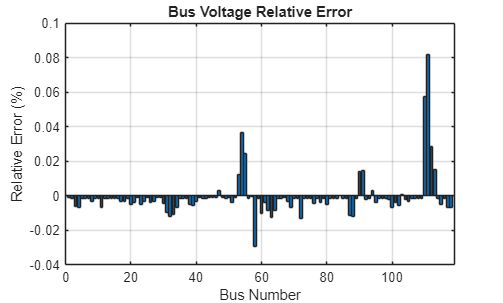

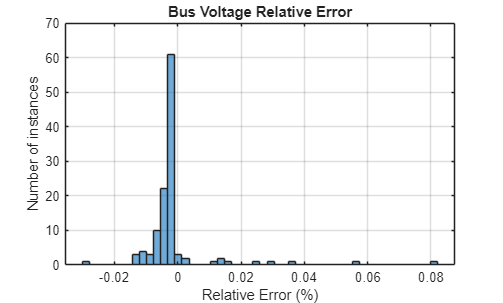

compareVoltage

Plot the frequency response of each synchronous machine - offset the time by 10 seconds so the trip occurs at 1 second on the plot.

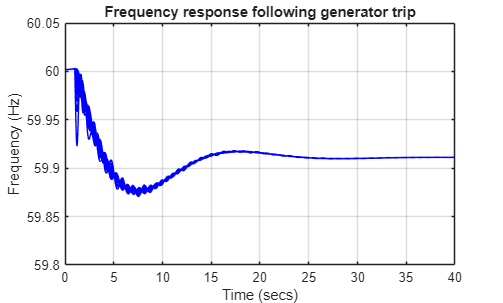

figure,plot(out.w.Time-10,reshape(out.w.Data,54,numel(out.w.Time)),'b'),grid
axis([0 40 59.8 60.05])
title('Frequency response following generator trip')
xlabel('Time (secs)'),ylabel('Frequency (Hz)')

## Subsequent Use of the System Model

Once the steps in this document have been taken, you do not need to rebuild the system. For subsequent simulations, load the appropriate data files and top-level model.

END OF DOCUMENT